# Documentation

The function "run7Box.m" simulates the carbon cycle on seven reservoirs on Earth based on the paper by [1] . The model is based on the box model approach, where each reservoir is represented by a box that exchanges carbon with other boxes through various processes. 

The model accounts for emissions from fossil fuels, land use change, and other human activities, and it calculates the resulting atmospheric CO2 concentrations. The model can be run with or without a buffer factor that accounts for the effect of the oceans on atmospheric CO2 concentrations. 

The function takes various parameters, including the simulation time step, the simulation duration, and the emissions data, and it returns the atmospheric CO2 concentrations over time. 

This documentation includes information on how to use the function, how to set the input parameters, and how to interpret the output results. Additionally, it provides examples of how to run the function with different input parameters and how to plot the results.

**References**

[1] Tomizuka, A. (2009). Is a box model effective for understanding the carbon cycle?. American Journal of Physics, 77(2), 156-163.

## Initialisation

This section initializes the simulation by setting up the number of boxes in the model, and defines the  time step, simulation duration, and time vector. It then loads the  emissions data for fossil fuel and industry, scales it to the  appropriate units, and interpolates it to match the time vector. The  code does the same for the emissions data from land use change, then  plots both emissions over time. 

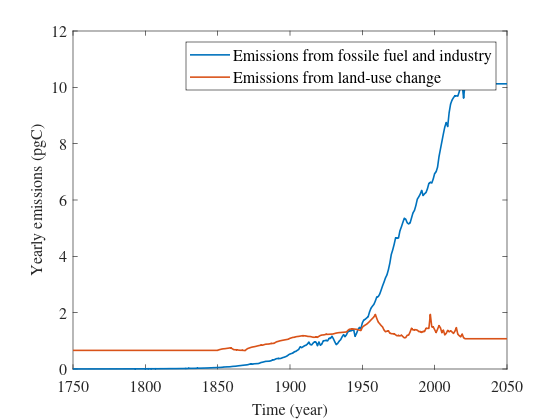

clearvars;close all;clc;
 set(0, 'DefaultFigureRenderer', 'painters');
% box 1 = atmosphere
% box 2 = surface ocean
% box 3 = intermediate ocean
% box 4 = deep ocean
% box 5 = sediment
% box 6 = biosphere
% box 7 = soil
Nbox = 7;

% Define time step and simulation duration
dt = 1; % Time step (yr)
tmax = 300; % Simulation duration (yr)
t = (0:dt:tmax)+1750;
N = numel(t);
%% Load emissions data

% Emissions from Fossile fual and industry
clf;close all
load('gamma_ourWorldInData.mat','Year','Total')
Total = Total*3/11*1e6/1e15;

% Emissions from land use change
load('delta_ourWorldInData.mat','year','Land_use_change')
Land_use_change = Land_use_change*3/11*1e6/1e15;

delta = interp1(year(~isnan(year)),Land_use_change(~isnan(year)),t,'nearest','extrap');
gamma = interp1(Year(~isnan(Year)),Total(~isnan(Year)),t,'nearest','extrap');

clf;close all;
figure
plot(t,gamma,t,delta,'linewidth',1.2);
xlabel('Time (year)')
ylabel('Yearly emissions (pgC)')
set(gcf,'color','w')
legend('Emissions from fossile fuel and industry','Emissions from land-use change')
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

## Run the simulation setup

This section runs the 7-box carbon cycle model with different input  scenarios. The first simulation calculates the CO2 concentration in the  atmosphere with the buffer factor and the `gamma` and `delta` input data over time. The second simulation calculates the CO2 concentration  in the atmosphere without the buffer factor. The third simulation calculates  the CO2 concentration in the atmosphere without any emissions from land  use. The fourth simulation calculates the CO2 concentration in the atmosphere  assuming no emissions from human activities, specifically from fossil  fuel and industry (`gamma`) and land use change (`delta`).

% With buffer factor
%  beta is the fertilization factor
[C_CO2] = run7Box(t,gamma,delta,'beta',0.38);

% Without buffer factor
[C_CO2_noBuffer] = run7Box(t,gamma,delta,'buffer',0,'beta',0.38);

% Without emissions from land use
[C_CO2_no_delta] = run7Box(t,gamma,delta.*0,'beta',0.38);

% Without emissions from land use or human activities
[C_CO2_preIndustrial] = run7Box(t,gamma.*0,delta.*0,'beta',0.38);

## Plot results

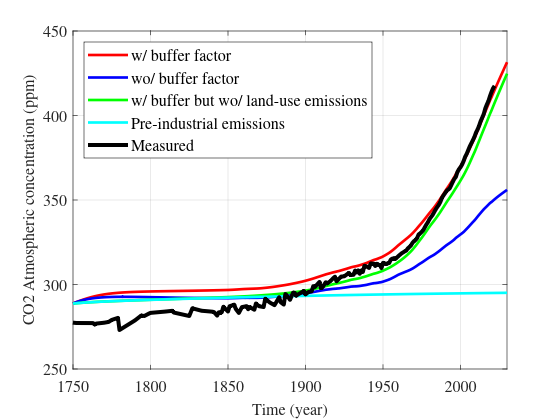

clf;close all;figure
grid on
plot(t, C_CO2(1,:),'r','LineWidth',2);
hold on
plot(t, C_CO2_noBuffer(1,:),'b','LineWidth',2);
plot(t, C_CO2_no_delta(1,:),'g','LineWidth',2);
plot(t, C_CO2_preIndustrial(1,:),'c','LineWidth',2);
m = readtable('climate-change.csv', "Range" , [846 2 2777 3]); %dlmread
plot(m{:,1},inpaint_nans(m{:,2},4),'k','linewidth',3)
xlim([1750 2030])
legend('w/ buffer factor',...
    'wo/ buffer factor',...
    'w/ buffer but wo/ land-use emissions',...
    'Pre-industrial emissions',...
    'Measured','location','northwest')

xlabel('Time (year)')
grid on
ylabel('CO2 Atmospheric concentration (ppm)')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')